[signal,fs]=audioread("mhint_01_01.wav");
disp(fs);

       16000



sound(signal,fs);

[p1,q1]=rat(20e3/fs);

     5



     4



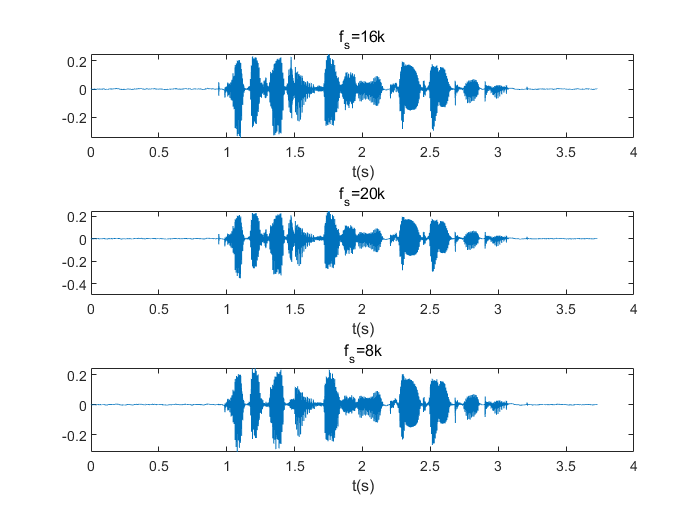

signalof20000=resample(signal,p1,q1);
sound(signalof20000,20e3)

[p2,q2]=rat(8e3/fs);
signalof8000=resample(signal,p2,q2);
sound(signalof8000,8e3)

figure
subplot(3,1,1)
plot((0:length(signal)-1)/fs,signal);
xlabel('t(s)');
title('f_s=16k');
subplot(3,1,2)
plot((0:length(signalof20000)-1)/20000,signalof20000);
xlabel('t(s)');
title('f_s=20k');
subplot(3,1,3)
plot((0:length(signalof8000)-1)/8000,signalof8000);
xlabel('t(s)');
title('f_s=8k');

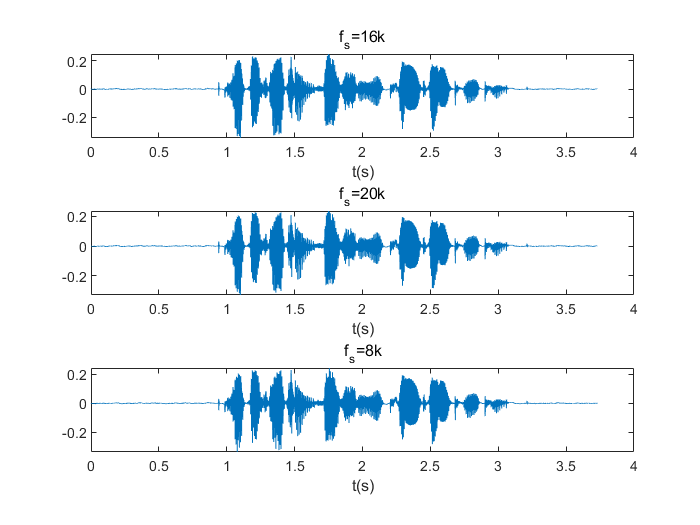


xoriginal=(0:length(signal)-1)/fs;
xof20000=0:1/20000:(length(signal)/fs*20000-1)/20000;
vqof20000=interp1(xoriginal,signal,xof20000);
xof8000=0:1/8000:(length(signal)/fs*8000-1)/8000;
vqof8000=interp1(xoriginal,signal,xof8000);
figure
subplot(3,1,1)
plot((0:length(signal)-1)/fs,signal);
xlabel('t(s)');
title('f_s=16k');
subplot(3,1,2)
plot((0:length(vqof20000)-1)/20000,vqof20000);
xlabel('t(s)');
title('f_s=20k');
subplot(3,1,3)
plot((0:length(vqof8000)-1)/8000,vqof8000);
xlabel('t(s)');
title('f_s=8k');